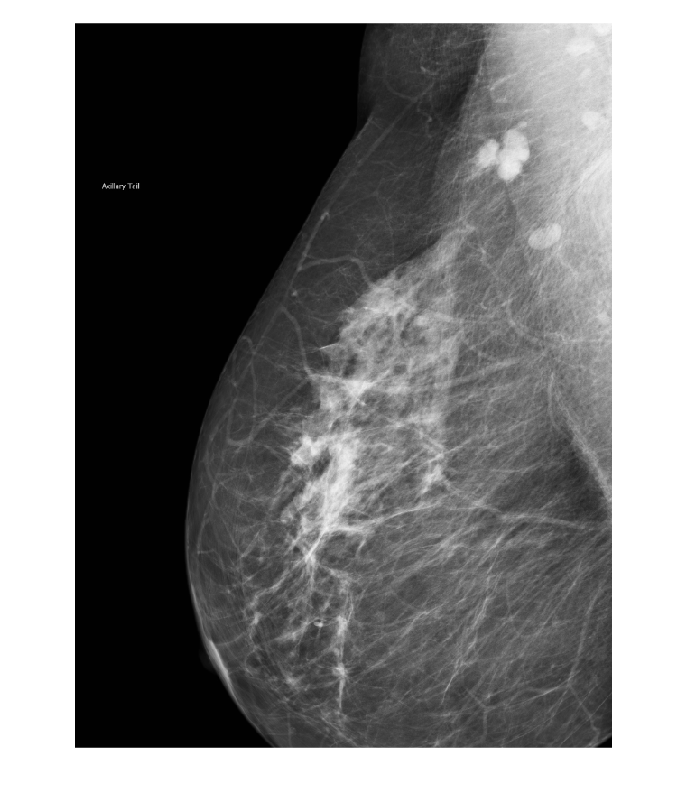

% import Medical Image into Workspace
% Step1: Read the image

Original=imread('Straight_Lateral.png');
imshow(Original);

% create Meta Data for change format from png to DICOM
%create Meta data for DICOM image converter

% Step2: Convert to grayscale if the image is in color
if size(Original, 3) == 3
    I_gray = rgb2gray(Original);
else
    I_gray = Original;
end

% Step 9: Create DICOM metadata for mammography
metadata = struct();
metadata.PatientName = 'Test Patient';
metadata.PatientID = '1001';
metadata.PatientBirthDate = '20240101'; % Format: YYYYMMDD
metadata.PatientSex = 'F'; % Female
metadata.StudyInstanceUID = dicomuid;
metadata.SeriesInstanceUID = dicomuid;
metadata.SOPInstanceUID = dicomuid;
metadata.SOPClassUID = '1.2.840.10008.5.1.4.1.1.1.2'; % For Digital Mammography X-Ray Image Storage - For Processing
metadata.Modality = 'MG'; % Mammography
metadata.ImageType = 'DERIVED\SECONDARY';
metadata.StudyID = '1';
metadata.SeriesNumber = 1;
metadata.InstanceNumber = 1;
metadata.Rows = size(I_gray, 1);
metadata.Columns = size(I_gray, 2);
metadata.BitsAllocated = 8;
metadata.BitsStored = 8;
metadata.HighBit = 7;
metadata.PixelRepresentation = 0;
metadata.SamplesPerPixel = 1;
metadata.PhotometricInterpretation = 'MONOCHROME2';
metadata.StudyDate = '20240101'; % Example study date
metadata.StudyTime = '120000'; % Example study time (HHMMSS)
metadata.ReferringPhysicianName = 'Dr. Example';
metadata.InstitutionName = 'UIC Hospital';
metadata.Manufacturer = 'UI Health Manufacturer';
metadata.ManufacturerModelName = 'Mammography';

% Step 10: Write to DICOM using 'CreateMode' option
dicomwrite(I_gray, 'Straight_Lateral.dcm', metadata, 'CreateMode', 'Copy');

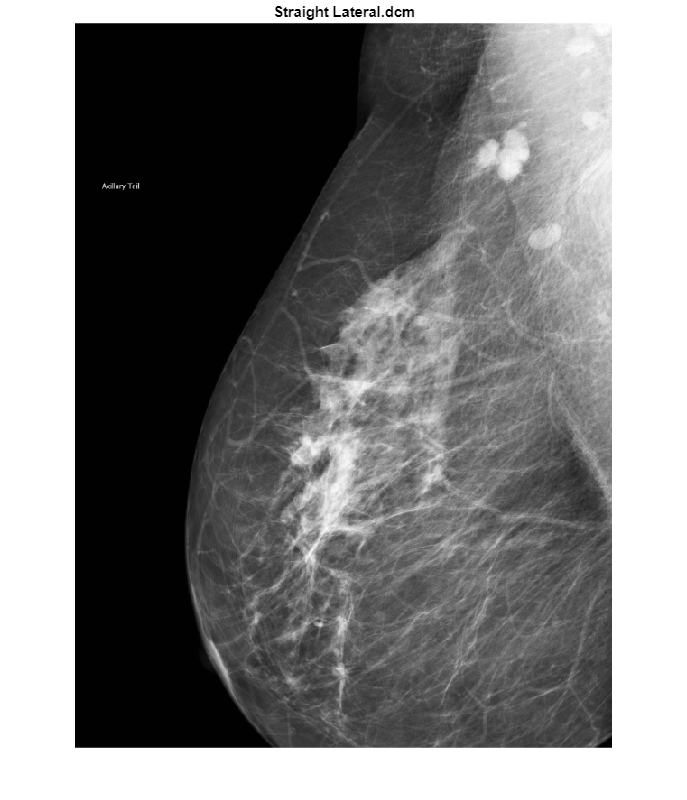

Input_Image=dicomread("Straight_Lateral.dcm");
imshow(Input_Image,DisplayRange=[])
title('Straight Lateral.dcm');

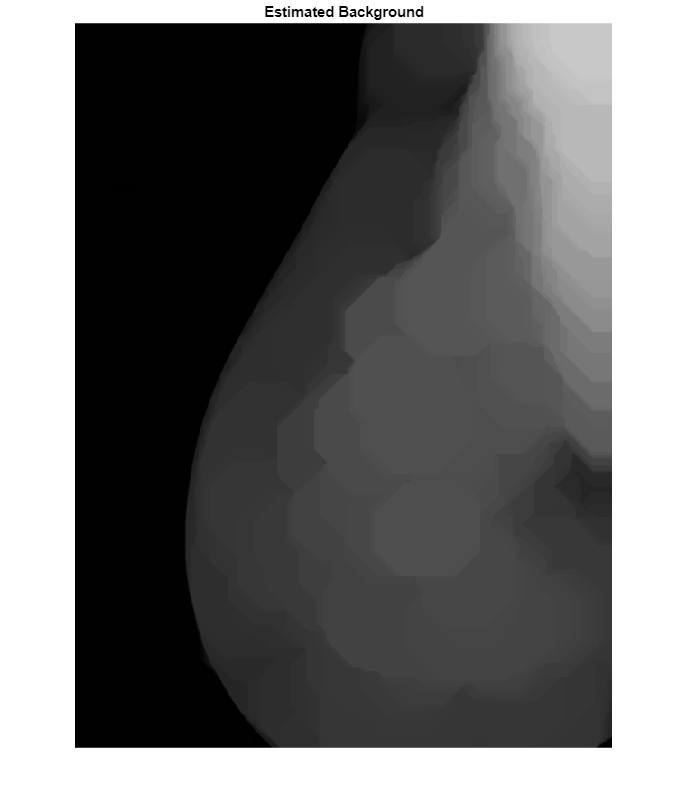

% second step in workflow is removing background, denoising, registeration,
% normalization
%Step1 :Background removal

% Step3: Estimate the background using morphological opening Adjust the size as needed
se = strel('disk', 50); 
background = imopen(Input_Image, se);
imshow(background);
title('Estimated Background');

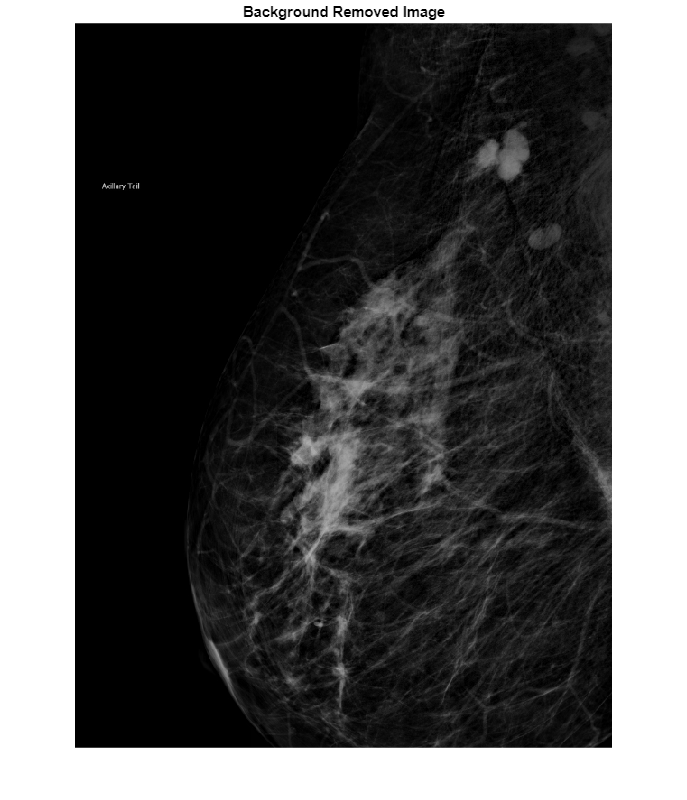


% Step4: Subtract the background from the grayscale image
I_background_removed = Input_Image - background;
imshow(I_background_removed);
title('Background Removed Image');

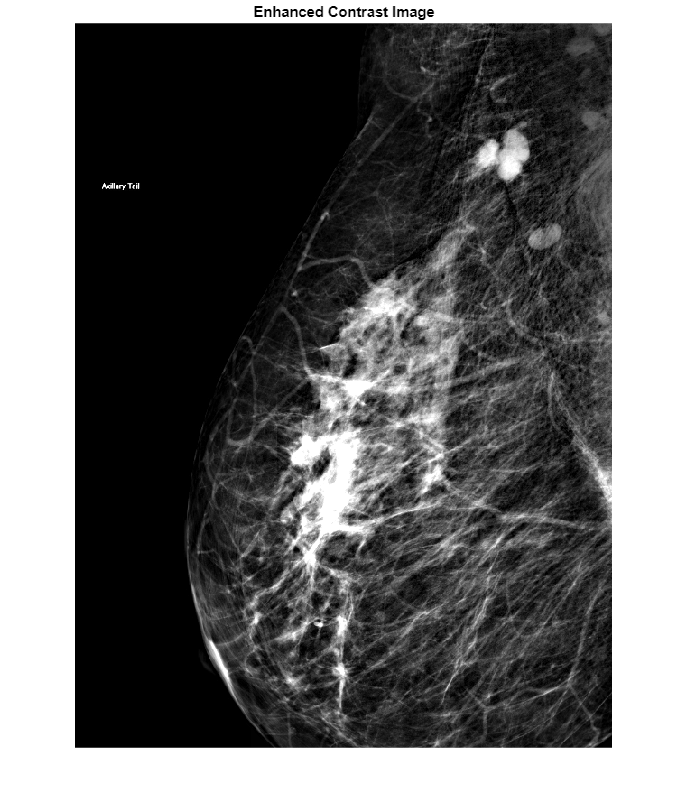



% Step 4: Enhance contrast of the background-removed image
I_enhanced = imadjust(I_background_removed);
imshow(I_enhanced);
title('Enhanced Contrast Image');

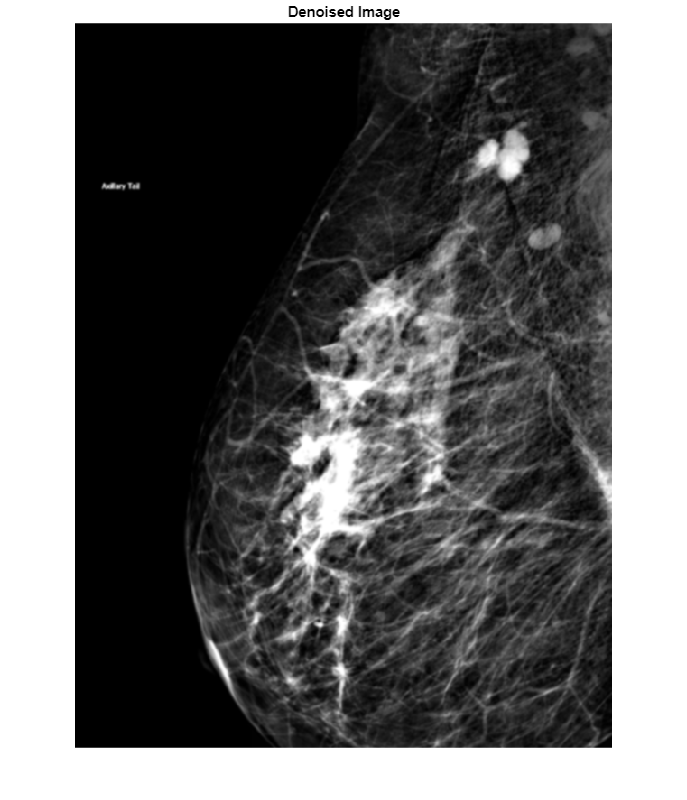


% Step 5: Denoise the image using a Gaussian filter
I_denoised = imgaussfilt(I_enhanced, 1); 
imshow(I_denoised);
title('Denoised Image');

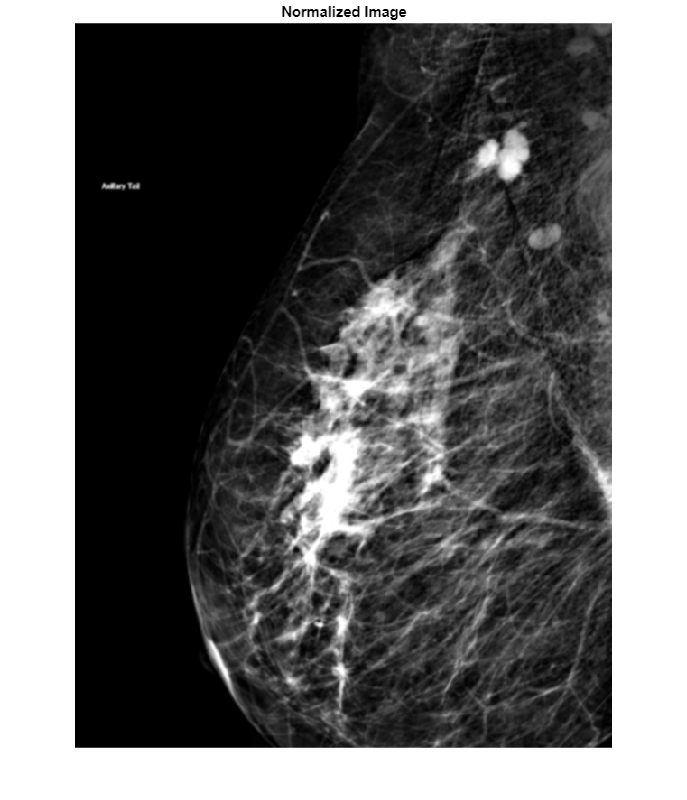


% Step 6: Intensity Normalization
imMax = prctile(I_denoised(:), 99.5);
imMin = prctile(I_denoised(:), 0.5);
imNormalized = rescale(I_denoised, 0, 1, 'InputMin', imMin, 'InputMax', imMax);
imshow(imNormalized);
title('Normalized Image');


% Step 7: Save the final image as DICOM
outputFile = 'Straight_Lateral_output.dcm';
dicomwrite(uint8(imNormalized * 256), outputFile); % Convert to uint16 for DICOM format

imwrite(imNormalized, 'imNormalized.png');



% Example 2D image and mask
image2D = uint8(randi([0, 255], 256, 256)); % Replace with your actual 2D image data
mask2D = uint8(randi([0, 1], 256, 256));    % Replace with your actual 2D mask data

% Convert 2D image and mask to 3D by adding an extra dimension
image3D = repmat(image2D, [1, 1, 1]);  % Adding a singleton dimension to create a 3D volume
mask3D = repmat(mask2D, [1, 1, 1]);    % Adding a singleton dimension to create a 3D volume

% Assuming you have a function to extract radiomics features, similar to the radiomics toolbox
% Here, we create a custom function for feature extraction

% Define the custom function (this is a placeholder, replace with actual feature extraction logic)
function features = extractRadiomicsFeatures(image, mask)
    % Example feature extraction (mean intensity)
    features.meanIntensity = mean(image(mask > 0));
    
    % Add more features as needed
end

% Extract radiomics features
features = extractRadiomicsFeatures(image3D, mask3D);

% Display or process the features
disp(features);

    meanIntensity: 127.3980



%1- Read and process the original Image and Normal Lymphnode
NL_Img = dicomread("Straight_Lateral_output.dcm")

NL_Img = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

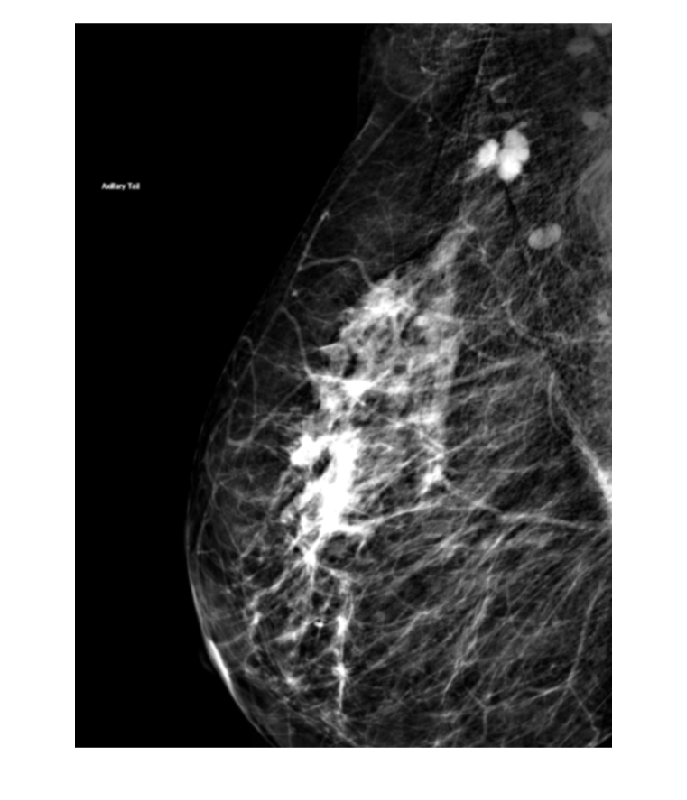

NL_Img = im2gray(NL_Img);
imshow(NL_Img(:,:,1),[])

NL_Img = cat(3, NL_Img, zeros([size(NL_Img) 2], class(NL_Img)));
volGeometry = medicalref3d(size(NL_Img));
Data = medicalVolume(NL_Img, volGeometry);
Data.Voxels = squeeze(Data.Voxels);
%
matFilePath = 'MedicalLabelingSession_NormalLymph/LabelData/Straight_Lateral_output.mat';
loadedData = load(matFilePath);
fieldNames = fieldnames(loadedData);
disp(fieldNames);

    {'labels'}



Maskimg = loadedData.labels

Maskimg = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

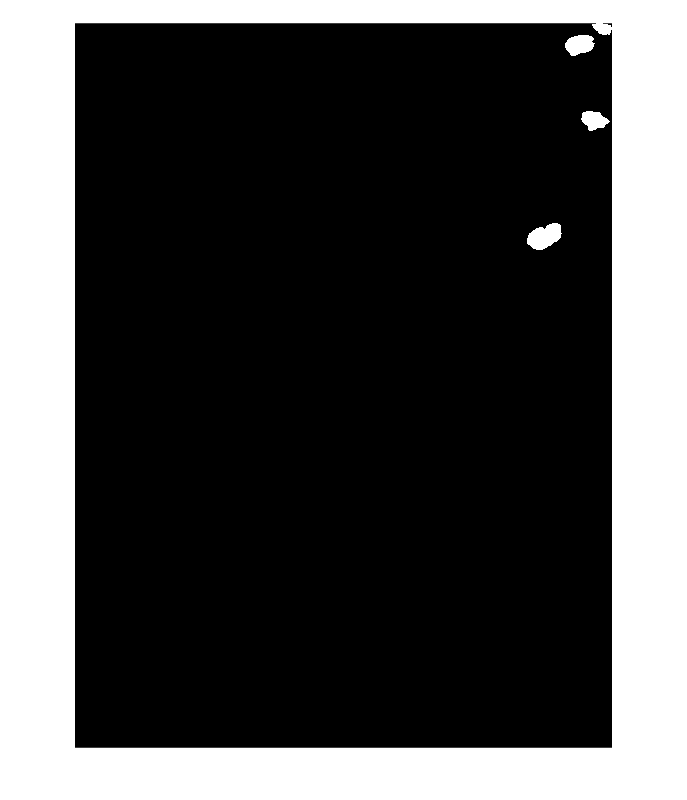

% Read and process the mask image
imshow(Maskimg(:,:,1),[])

    Maskimg = im2uint8(Maskimg);
    Maskimg = cat(3,Maskimg,zeros([size(Maskimg) 2],class(Maskimg)));
    volGeometry = medicalref3d(size(Maskimg));
    RoiData = medicalVolume(Maskimg,volGeometry);
    RoiData.Voxels = squeeze(RoiData.Voxels);



% Call the radiomics function
NL_R = radiomics(Data, RoiData);
% around 10 seconds

% Extract intensity features
NL_Int = intensityFeatures(NL_R,Type="all",SubType="2D")

NL_Int = 1×50 table
    LabelID    LocalIntensityPeak2D    GlobalIntensityPeak2D    MeanIntensity2D    IntensityVariance2D    IntensitySkewness2D    IntensityKurtosis2D    MedianIntensity2D    MinimumIntensity2D    TenthIntensityPercentile2D    NinetiethIntensityPercentile2D    MaximumIntensity2D    IntensityInterquartileRange2D    IntensityRange2D    MeanAbsoluteDeviation2D    RobustMeanAbsoluteDeviation2D    MedianAbsoluteDeviation2D    CoefficientOfVariation2D    QuartileCoefficientOfDispersion2D    IntensityEnergy2D    RootMeanSquare2D    MeanDiscretisedIntensity2D    DiscretisedIntensityVariance2D

% around 10 seconds
%% Extract texture features
NL_tex = textureFeatures(NL_R,Type="all",SubType="2D")

NL_tex = 1×137 table
    LabelID    JointMaximumAveraged2D    JointAverageAveraged2D    JointVarianceAveraged2D    JointEntropyAveraged2D    DifferenceAverageAveraged2D    DifferenceVarianceAveraged2D    DifferenceEntropyAveraged2D    SumAverageAveraged2D    SumVarianceAveraged2D    SumEntropyAveraged2D    AngularSecondMomentAveraged2D    ContrastAveraged2D    DissimilarityAveraged2D    InverseDifferenceAveraged2D    NormalisedInverseDifferenceAveraged2D    InverseDifferenceMomentAveraged2D    NormalisedInverseDifferenceMomentAveraged2D    InverseVarianceAveraged2D    CorrelationAveraged2D    AutoCorrelationAveraged2D    Cluste

% around 10 seconds
% Extract shape features
NL_S = shapeFeatures(NL_R, SubType="2D");
NL_S = removevars(NL_S, "LabelID");
NLradiomicsFeaturesTrain(1, :) = NL_S

NLradiomicsFeaturesTrain = 1×23 table
    VolumeMesh2D    VolumeVoxelCount2D    SurfaceAreaMesh2D    SurfaceVolumeRatio2D    Compactness1_2D    Compactness2_2D    SphericalDisproportion2D    Sphericity2D    Asphericity2D    CentreOfMassShift2D    Maximum3dDiameter2D    MajorAxisLength2D    MinorAxisLength2D    LeastAxisLength2D    Elongation2D    Flatness2D    VolumeDensityAABB_2D    AreaDensityAABB_2D    VolumeDensityAEE_2D    AreaDensityAEE_2D    VolumeDensityConvexHull2D    AreaDensityConvexHull2D    IntegratedIntensity2D
    ____________    __________________    <s

%2- Read and process the original Image and AbNormal Lymphnode
ABL_Img =dicomread("Straight_Lateral_output.dcm")

ABL_Img = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 


ABl_Img = im2gray(ABL_Img);
imshow(ABL_Img(:,:,1),[])

ABL_Img = cat(3, ABL_Img, zeros([size(ABL_Img) 2], class(ABL_Img)));
volGeometry = medicalref3d(size(ABL_Img));
Data = medicalVolume(ABL_Img, volGeometry);
Data.Voxels = squeeze(Data.Voxels);
%
matFilePath = 'MedicalLabelingSession_AbNormalLymph/LabelData/Straight_Lateral_output.mat';
loadedData = load(matFilePath);
fieldNames = fieldnames(loadedData);
disp(fieldNames);

    {'labels'}



Maskimg = loadedData.labels

Maskimg = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

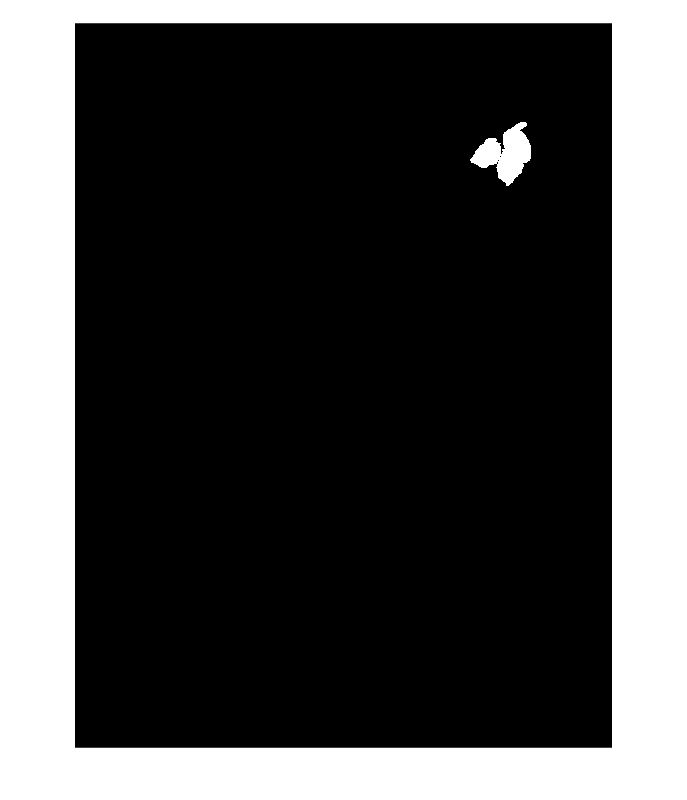

% Read and process the mask image
imshow(Maskimg(:,:,1),[])

    Maskimg = im2uint8(Maskimg);
    Maskimg = cat(3,Maskimg,zeros([size(Maskimg) 2],class(Maskimg)));
    volGeometry = medicalref3d(size(Maskimg));
    RoiData = medicalVolume(Maskimg,volGeometry);
    RoiData.Voxels = squeeze(RoiData.Voxels);



% Call the radiomics function
ABL_R = radiomics(Data, RoiData);
% around 10 seconds

% Extract intensity features
ABL_Int = intensityFeatures(ABL_R,Type="all",SubType="2D")

ABL_Int = 1×50 table
    LabelID    LocalIntensityPeak2D    GlobalIntensityPeak2D    MeanIntensity2D    IntensityVariance2D    IntensitySkewness2D    IntensityKurtosis2D    MedianIntensity2D    MinimumIntensity2D    TenthIntensityPercentile2D    NinetiethIntensityPercentile2D    MaximumIntensity2D    IntensityInterquartileRange2D    IntensityRange2D    MeanAbsoluteDeviation2D    RobustMeanAbsoluteDeviation2D    MedianAbsoluteDeviation2D    CoefficientOfVariation2D    QuartileCoefficientOfDispersion2D    IntensityEnergy2D    RootMeanSquare2D    MeanDiscretisedIntensity2D    DiscretisedIntensityVariance2D

% around 10 seconds
%% Extract texture features
ABL_tex = textureFeatures(ABL_R,Type="all",SubType="2D")

ABL_tex = 1×137 table
    LabelID    JointMaximumAveraged2D    JointAverageAveraged2D    JointVarianceAveraged2D    JointEntropyAveraged2D    DifferenceAverageAveraged2D    DifferenceVarianceAveraged2D    DifferenceEntropyAveraged2D    SumAverageAveraged2D    SumVarianceAveraged2D    SumEntropyAveraged2D    AngularSecondMomentAveraged2D    ContrastAveraged2D    DissimilarityAveraged2D    InverseDifferenceAveraged2D    NormalisedInverseDifferenceAveraged2D    InverseDifferenceMomentAveraged2D    NormalisedInverseDifferenceMomentAveraged2D    InverseVarianceAveraged2D    CorrelationAveraged2D    AutoCorrelationAveraged2D    Clust

% around 10 seconds
% Extract shape features
ABL_S = shapeFeatures(ABL_R, SubType="2D");
ABL_S = removevars(ABL_S, "LabelID");
ABLradiomicsFeaturesTrain(1, :) =ABL_S

ABLradiomicsFeaturesTrain = 1×23 table
    VolumeMesh2D    VolumeVoxelCount2D    SurfaceAreaMesh2D    SurfaceVolumeRatio2D    Compactness1_2D    Compactness2_2D    SphericalDisproportion2D    Sphericity2D    Asphericity2D    CentreOfMassShift2D    Maximum3dDiameter2D    MajorAxisLength2D    MinorAxisLength2D    LeastAxisLength2D    Elongation2D    Flatness2D    VolumeDensityAABB_2D    AreaDensityAABB_2D    VolumeDensityAEE_2D    AreaDensityAEE_2D    VolumeDensityConvexHull2D    AreaDensityConvexHull2D    IntegratedIntensity2D
    ____________    __________________    <


%3- Read and process the original Image and Normal Fat
NFat_Img =dicomread("Straight_Lateral_output.dcm")

NFat_Img = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


NFat_Img = im2gray(NFat_Img);
imshow(NFat_Img(:,:,1),[])

NFat_Img = cat(3, NFat_Img, zeros([size(NFat_Img) 2], class(NFat_Img)));
volGeometry = medicalref3d(size(NFat_Img));
Data = medicalVolume(NFat_Img, volGeometry);
Data.Voxels = squeeze(Data.Voxels);
%
matFilePath = 'MedicalLabelingSession_NormalFat/LabelData/Straight_Lateral_output.mat';
loadedData = load(matFilePath);
fieldNames = fieldnames(loadedData);
disp(fieldNames);

    {'labels'}



Maskimg = loadedData.labels

Maskimg = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

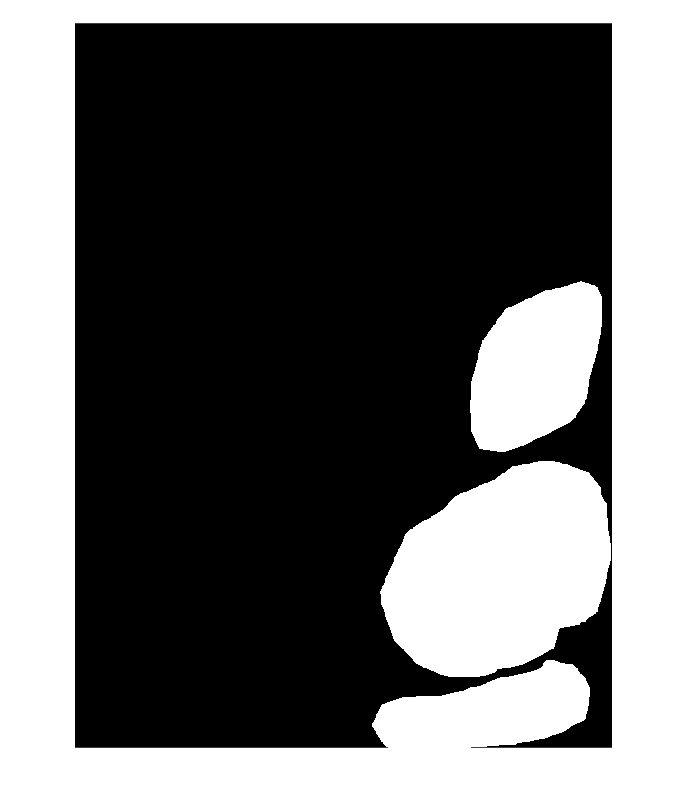

% Read and process the mask image
imshow(Maskimg(:,:,1),[])

    Maskimg = im2uint8(Maskimg);
    Maskimg = cat(3,Maskimg,zeros([size(Maskimg) 2],class(Maskimg)));
    volGeometry = medicalref3d(size(Maskimg));
    RoiData = medicalVolume(Maskimg,volGeometry);
    RoiData.Voxels = squeeze(RoiData.Voxels);



% Call the radiomics function
NFat_R = radiomics(Data, RoiData);
% around 10 seconds

% Extract intensity features
NFat_Int = intensityFeatures(NFat_R,Type="all",SubType="2D")

NFat_Int = 1×50 table
    LabelID    LocalIntensityPeak2D    GlobalIntensityPeak2D    MeanIntensity2D    IntensityVariance2D    IntensitySkewness2D    IntensityKurtosis2D    MedianIntensity2D    MinimumIntensity2D    TenthIntensityPercentile2D    NinetiethIntensityPercentile2D    MaximumIntensity2D    IntensityInterquartileRange2D    IntensityRange2D    MeanAbsoluteDeviation2D    RobustMeanAbsoluteDeviation2D    MedianAbsoluteDeviation2D    CoefficientOfVariation2D    QuartileCoefficientOfDispersion2D    IntensityEnergy2D    RootMeanSquare2D    MeanDiscretisedIntensity2D    DiscretisedIntensityVariance2D

% around 10 seconds
%% Extract texture features
NFat_tex = textureFeatures(NFat_R,Type="all",SubType="2D")

NFat_tex = 1×137 table
    LabelID    JointMaximumAveraged2D    JointAverageAveraged2D    JointVarianceAveraged2D    JointEntropyAveraged2D    DifferenceAverageAveraged2D    DifferenceVarianceAveraged2D    DifferenceEntropyAveraged2D    SumAverageAveraged2D    SumVarianceAveraged2D    SumEntropyAveraged2D    AngularSecondMomentAveraged2D    ContrastAveraged2D    DissimilarityAveraged2D    InverseDifferenceAveraged2D    NormalisedInverseDifferenceAveraged2D    InverseDifferenceMomentAveraged2D    NormalisedInverseDifferenceMomentAveraged2D    InverseVarianceAveraged2D    CorrelationAveraged2D    AutoCorrelationAveraged2D    Clus

% around 10 seconds
% Extract shape features
NFat_S = shapeFeatures(NFat_R, SubType="2D");
NFat_S = removevars(NFat_S, "LabelID");
NFatLradiomicsFeaturesTrain(1, :) =NFat_S

NFatLradiomicsFeaturesTrain = 1×23 table
    VolumeMesh2D    VolumeVoxelCount2D    SurfaceAreaMesh2D    SurfaceVolumeRatio2D    Compactness1_2D    Compactness2_2D    SphericalDisproportion2D    Sphericity2D    Asphericity2D    CentreOfMassShift2D    Maximum3dDiameter2D    MajorAxisLength2D    MinorAxisLength2D    LeastAxisLength2D    Elongation2D    Flatness2D    VolumeDensityAABB_2D    AreaDensityAABB_2D    VolumeDensityAEE_2D    AreaDensityAEE_2D    VolumeDensityConvexHull2D    AreaDensityConvexHull2D    IntegratedIntensity2D
    ____________    __________________   

%4- Read and process the original Image and Normal Part
NPart_Img =dicomread("Straight_Lateral_output.dcm")

NPart_Img = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   


NPart_Img = im2gray(NPart_Img);
imshow(NPart_Img(:,:,1),[])

NPart_Img = cat(3, NPart_Img, zeros([size(NPart_Img) 2], class(NPart_Img)));
volGeometry = medicalref3d(size(NPart_Img));
Data = medicalVolume(NPart_Img, volGeometry);
Data.Voxels = squeeze(Data.Voxels);
%
matFilePath = 'MedicalLabelingSession_NormalPart/LabelData/Straight_Lateral_output.mat';
loadedData = load(matFilePath);
fieldNames = fieldnames(loadedData);
disp(fieldNames);

    {'labels'}



Maskimg = loadedData.labels

Maskimg = 803×595 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

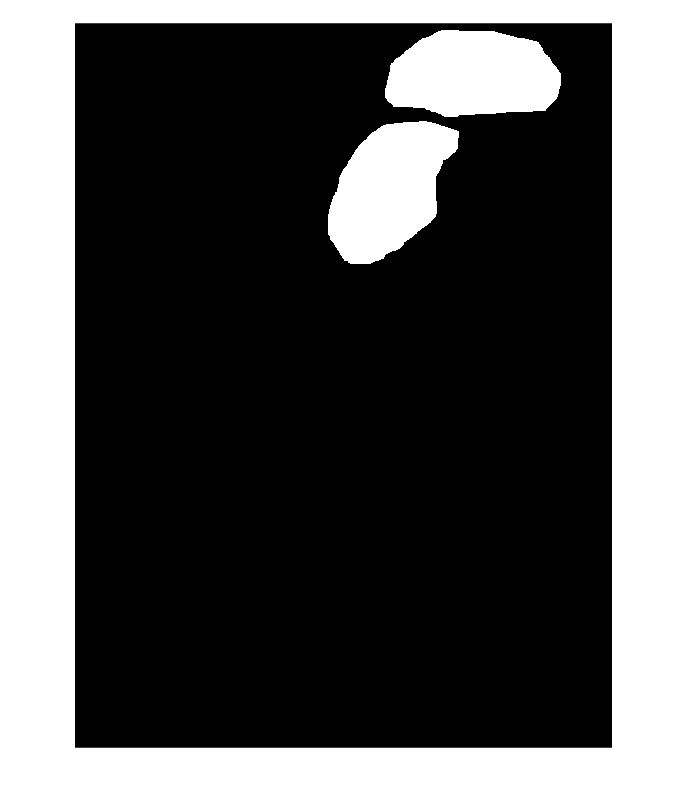

% Read and process the mask image
imshow(Maskimg(:,:,1),[])

    Maskimg = im2uint8(Maskimg);
    Maskimg = cat(3,Maskimg,zeros([size(Maskimg) 2],class(Maskimg)));
    volGeometry = medicalref3d(size(Maskimg));
    RoiData = medicalVolume(Maskimg,volGeometry);
    RoiData.Voxels = squeeze(RoiData.Voxels);



% Call the radiomics function
NPart_R = radiomics(Data, RoiData);
% around 10 seconds

% Extract intensity features
NPart_Int = intensityFeatures(NPart_R,Type="all",SubType="2D")

NPart_Int = 1×50 table
    LabelID    LocalIntensityPeak2D    GlobalIntensityPeak2D    MeanIntensity2D    IntensityVariance2D    IntensitySkewness2D    IntensityKurtosis2D    MedianIntensity2D    MinimumIntensity2D    TenthIntensityPercentile2D    NinetiethIntensityPercentile2D    MaximumIntensity2D    IntensityInterquartileRange2D    IntensityRange2D    MeanAbsoluteDeviation2D    RobustMeanAbsoluteDeviation2D    MedianAbsoluteDeviation2D    CoefficientOfVariation2D    QuartileCoefficientOfDispersion2D    IntensityEnergy2D    RootMeanSquare2D    MeanDiscretisedIntensity2D    DiscretisedIntensityVariance2D

% around 10 seconds
%% Extract texture features
NPart_tex = textureFeatures(NPart_R,Type="all",SubType="2D")

NPart_tex = 1×137 table
    LabelID    JointMaximumAveraged2D    JointAverageAveraged2D    JointVarianceAveraged2D    JointEntropyAveraged2D    DifferenceAverageAveraged2D    DifferenceVarianceAveraged2D    DifferenceEntropyAveraged2D    SumAverageAveraged2D    SumVarianceAveraged2D    SumEntropyAveraged2D    AngularSecondMomentAveraged2D    ContrastAveraged2D    DissimilarityAveraged2D    InverseDifferenceAveraged2D    NormalisedInverseDifferenceAveraged2D    InverseDifferenceMomentAveraged2D    NormalisedInverseDifferenceMomentAveraged2D    InverseVarianceAveraged2D    CorrelationAveraged2D    AutoCorrelationAveraged2D    Clu

% around 10 seconds
% Extract shape features
NPart_S = shapeFeatures(NPart_R, SubType="2D");
NPart_S = removevars(NPart_S, "LabelID");
NPartLradiomicsFeaturesTrain(1, :)=NPart_S

NPartLradiomicsFeaturesTrain = 1×23 table
    VolumeMesh2D    VolumeVoxelCount2D    SurfaceAreaMesh2D    SurfaceVolumeRatio2D    Compactness1_2D    Compactness2_2D    SphericalDisproportion2D    Sphericity2D    Asphericity2D    CentreOfMassShift2D    Maximum3dDiameter2D    MajorAxisLength2D    MinorAxisLength2D    LeastAxisLength2D    Elongation2D    Flatness2D    VolumeDensityAABB_2D    AreaDensityAABB_2D    VolumeDensityAEE_2D    AreaDensityAEE_2D    VolumeDensityConvexHull2D    AreaDensityConvexHull2D    IntegratedIntensity2D
    ____________    __________________  

%Combine and save data Texture
% 
T1 = NL_tex(1,:); 
T2 = ABL_tex(1,:);
T3 = NFat_tex(1,:);
T4 = NPart_tex(1,:);

% Combine the tables vertically
Texture_combined = vertcat(T1, T2, T3, T4);

% Set the row names
Texture_combined.Properties.RowNames = {'NormalLymph', 'AbNormalLymph', 'NormalFat', 'NormalPart'};

% Display the result
disp(Texture_combined);

                     LabelID    JointMaximumAveraged2D    JointAverageAveraged2D    JointVarianceAveraged2D    JointEntropyAveraged2D    DifferenceAverageAveraged2D    DifferenceVarianceAveraged2D    DifferenceEntropyAveraged2D    SumAverageAveraged2D    SumVarianceAveraged2D    SumEntropyAveraged2D    AngularSecondMomentAveraged2D    ContrastAveraged2D    DissimilarityAveraged2D    InverseDifferenceAveraged2D    NormalisedInverseDifferenceAveraged2D    InverseDifferenceMomentAveraged2D    NormalisedInverseDifferenceMomentAveraged2D    InverseVarianceAveraged2D    CorrelationAveraged2D    AutoCorrelationAveraged2D    ClusterTen

% save table in csv File
% Specify the file name and path
filename = 'Texture.csv';

% Write the table to a CSV file
writetable(Texture_combined, filename);

% combine and save data intensity
% 
I1 = NL_Int(1,:); 
I2 = ABL_Int(1,:);
I3 = NFat_Int(1,:);
I4 = NPart_Int(1,:);

% Combine the tables vertically
Intensity_combined = vertcat(I1, I2, I3, I4);

% Set the row names
Intensity_combined.Properties.RowNames = {'NormalLymph', 'AbNormalLymph', 'NormalFat', 'NormalPart'};

% Display the result
disp(Intensity_combined);

                     LabelID    LocalIntensityPeak2D    GlobalIntensityPeak2D    MeanIntensity2D    IntensityVariance2D    IntensitySkewness2D    IntensityKurtosis2D    MedianIntensity2D    MinimumIntensity2D    TenthIntensityPercentile2D    NinetiethIntensityPercentile2D    MaximumIntensity2D    IntensityInterquartileRange2D    IntensityRange2D    MeanAbsoluteDeviation2D    RobustMeanAbsoluteDeviation2D    MedianAbsoluteDeviation2D    CoefficientOfVariation2D    QuartileCoefficientOfDispersion2D    IntensityEnergy2D    RootMeanSquare2D    MeanDiscretisedIntensity2D    DiscretisedIntensityVariance2D   


% Specify the file name and path
filename = 'Intensity.csv';

% Write the table to a CSV file
writetable(Intensity_combined, filename);

% combine and save data Shape
% 
S1 = NL_S(1,:); 
S2 = ABL_S(1,:);
S3 = NFat_S(1,:);
S4 = NPart_S(1,:);

% Combine the tables vertically
Shape_combined = vertcat(S1, S2, S3, S4);

% Set the row names
Shape_combined.Properties.RowNames = {'NormalLymph', 'AbNormalLymph', 'NormalFat', 'NormalPart'};

% Display the result
disp(Shape_combined);

                     VolumeMesh2D    VolumeVoxelCount2D    SurfaceAreaMesh2D    SurfaceVolumeRatio2D    Compactness1_2D    Compactness2_2D    SphericalDisproportion2D    Sphericity2D    Asphericity2D    CentreOfMassShift2D    Maximum3dDiameter2D    MajorAxisLength2D    MinorAxisLength2D    LeastAxisLength2D    Elongation2D    Flatness2D    VolumeDensityAABB_2D    AreaDensityAABB_2D    VolumeDensityAEE_2D    AreaDensityAEE_2D    VolumeDensityConvexHull2D    AreaDensityConvexHull2D    IntegratedIntensity2D
                     ____________    __________________    

% Specify the file name and path
filename = 'Shape.csv';

% Write the table to a CSV file
writetable(Shape_combined, filename);

%plot texture 
% Load the combined table from the CSV file
Texture_combined = readtable('Texture.csv', 'ReadRowNames', true);

% Number of rows and columns in the table
[numRows, numCols] = size(Texture_combined);

% Define colors for the bars
colors = [0, 1, 0; 1, 0, 0; 0, 0, 1; 0, 0, 0]; % Green, Red, Blue, Black

% Define color names
colorNames = {'Green', 'Red', 'Blue', 'Black'};

% Ensure the colors array and color names have enough rows for the data
if numRows > size(colors, 1) || numRows > length(colorNames)
    error('Not enough colors or color names provided for the number of rows.');
end

% Create a new figure window
figure;

% Create a bar chart with groups of bars for each column
hBar = bar(table2array(Texture_combined)', 'grouped'); % Transpose to get columns as rows for bar function

% Set colors for each group of bars
for i = 1:numRows
    % Set color for each bar series (row)
    hBar(i).FaceColor = colors(i, :);
end

% Set the y-axis to logarithmic scale
set(gca, 'YScale', 'log');

% Add labels and title
xlabel('Columns');
ylabel('Values');
title('Bar Chart of Each Column with Logarithmic Scale');

% Set x-axis labels to column names
xticks(1:numCols);
xticklabels(Texture_combined.Properties.VariableNames);

% Create custom legend with color names
Texture_combined.Properties.RowNames = {'NormalLymph', 'AbNormalLymph', 'NormalFat', 'NormalPart'};

legendEntries = cell(numRows, 1); % Initialize cell array for legend entries
for i = 1:numRows
    legendEntries{i} = sprintf('%s', Texture_combined.Properties.RowNames{i});
end
legend(hBar, legendEntries, 'Location', 'best');

% Display grid
grid on;
% Adjust axis limits with padding
xPadding = 5; % Extend x-axis by 0.5 units on both sides
yPadding = 2; % Extend y-axis by 0.5 units on both sides

% Extend x-axis and y-axis limits
xLimits = xlim; % Get current x-axis limits

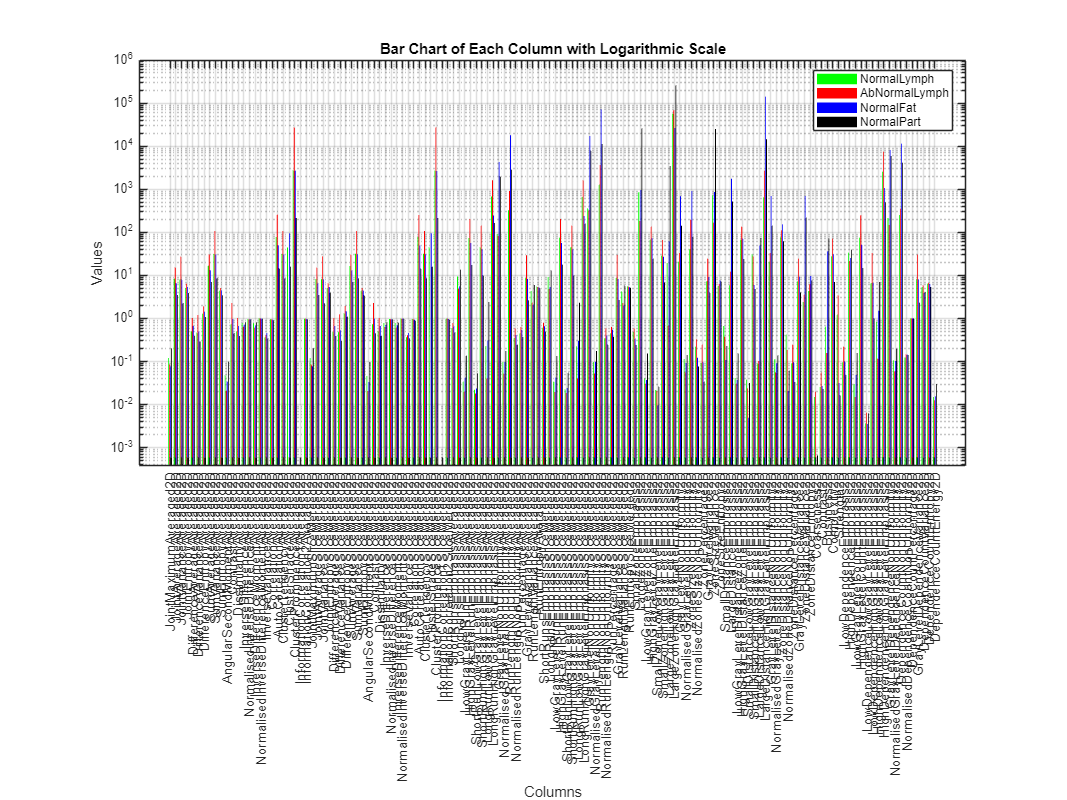

yLimits = ylim; % Get current y-axis limits

xlim([xLimits(1) - xPadding, xLimits(2) + xPadding]); % Extend x-axis
ylim([yLimits(1) - yPadding, yLimits(2) + yPadding]); % Extend y-axis
% Get the screen size
% To resize the figure window, you can set the 'Position' property
set(gcf, 'Position', [1, 1, 4800, 3600]); % Example: [left, bottom, width, height]

% find maximum variance for texture


% Calculate variance for each column in the table
columnVariances = var(table2array(Texture_combined)); % Convert table to matrix and calculate variance

% Sort the variances in descending order and get the indices of the top 10
[~, sortedIndices] = sort(columnVariances, 'descend');

numTopColumns = 10; % Number of top columns you want to select
top10Indices = sortedIndices(1:numTopColumns);

% Extract the top 10 columns from the table
top10Columns = Texture_combined(:, top10Indices);

% Display results
disp('Names of the top 10 columns with maximum variance:');

Names of the top 10 columns with maximum variance:


disp(Texture_combined.Properties.VariableNames(top10Indices));

    {'LargeZoneHighGrayLevelEmphasis2D'}    {'LargeDistanceHighGrayLevelEmphasis2D'}    {'RunLengthNonUniformitySliceMerged2D'}    {'ClusterProminenceSliceMerged2D'}    {'ClusterProminenceAveraged2D'}    {'LargeZoneEmphasis2D'}    {'ZoneSizeVariance2D'}    {'RunLengthNonUniformityAveraged2D'}    {'GrayLevelNonUniformitySliceMerged2D'}    {'DependenceCountNonUniformity2D'}



disp('Top 10 columns data:');

Top 10 columns data:


disp(top10Columns);

                     LargeZoneHighGrayLevelEmphasis2D    LargeDistanceHighGrayLevelEmphasis2D    RunLengthNonUniformitySliceMerged2D    ClusterProminenceSliceMerged2D    ClusterProminenceAveraged2D    LargeZoneEmphasis2D    ZoneSizeVariance2D    RunLengthNonUniformityAveraged2D    GrayLevelNonUniformitySliceMerged2D    DependenceCountNonUniformity2D
                     ________________________________    ____________________________________    ___________________________________    ______________________________    ___________________________    ___________________    __________________    ________________________________    ___________________________________    

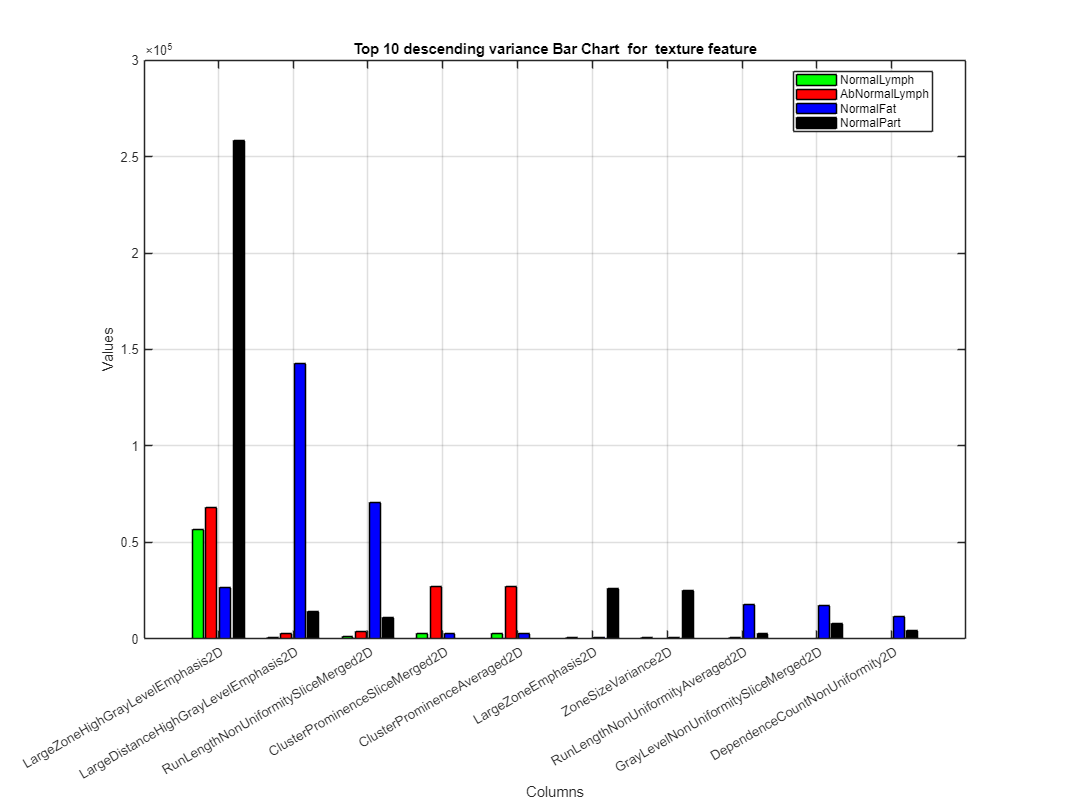

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%plot descending order texture feature

% Number of rows and columns in the table
[numRows, numCols] = size(top10Columns);

% Define colors for the bars
colors = [0, 1, 0; 1, 0, 0; 0, 0, 1; 0, 0, 0]; % Green, Red, Blue, Black
colorNames = {'Green', 'Red', 'Blue', 'Black'};

figure;

% Create a bar chart with groups of bars for each column
hBar = bar(table2array(top10Columns)', 'grouped'); 

% Set colors for each group of bars
for i = 1:numRows
    hBar(i).FaceColor = colors(i, :);
end

        % Set the y-axis to logarithmic scale
        %set(gca, 'YScale', 'log');

% Add labels and title
xlabel('Columns');
ylabel('Values');
title('Top 10 descending variance Bar Chart  for  texture feature');

% Set x-axis labels to column names
xticks(1:numCols);
xticklabels(top10Columns.Properties.VariableNames);

% Create custom legend with color names
Texture_combined.Properties.RowNames = {'NormalLymph', 'AbNormalLymph', 'NormalFat', 'NormalPart'};

legendEntries = cell(numRows, 1); % Initialize cell array for legend entries
for i = 1:numRows
    legendEntries{i} = sprintf('%s', Texture_combined.Properties.RowNames{i});
end
legend(hBar, legendEntries, 'Location', 'best');

% Display grid
grid on;
% Adjust axis limits with padding
xPadding = .5; 
yPadding = .5; 

% Extend x-axis and y-axis limits
xLimits = xlim; 
yLimits = ylim; 

xlim([xLimits(1) - xPadding, xLimits(2) + xPadding]); 
ylim([yLimits(1) - yPadding, yLimits(2) + yPadding]); 

set(gcf, 'Position', [1, 1, 4800, 3600]); %  [left, bottom, width, height]

%plot Intensity 
% Load the  Intensity combined table from the CSV file
Intensity_combined = readtable('Intensity.csv', 'ReadRowNames', true);

% Number of rows and columns in the table
[numRows, numCols] = size(Intensity_combined);

% Define colors for the bars
colors = [0, 1, 0; 1, 0, 0; 0, 0, 1; 0, 0, 0]; % Green, Red, Blue, Black

% Define color names
colorNames = {'Green', 'Red', 'Blue', 'Black'};

% Ensure the colors array and color names have enough rows for the data
if numRows > size(colors, 1) || numRows > length(colorNames)
    error('Not enough colors or color names provided for the number of rows.');
end

% Create a new figure window
figure;

% Create a bar chart with groups of bars for each column
hBar = bar(table2array(Intensity_combined)', 'grouped'); % Transpose to get columns as rows for bar function

% Set colors for each group of bars
for i = 1:numRows
    % Set color for each bar series (row)
    hBar(i).FaceColor = colors(i, :);
end

% Set the y-axis to logarithmic scale
set(gca, 'YScale', 'log');

% Add labels and title
xlabel('Columns');
ylabel('Values');
title('Intensity_combined Bar Chart with Logarithmic Scale');

% Set x-axis labels to column names
xticks(1:numCols);
xticklabels(Intensity_combined.Properties.VariableNames);

% Create custom legend with color names
Intensity_combined.Properties.RowNames = {'NormalLymph', 'AbNormalLymph', 'NormalFat', 'NormalPart'};

legendEntries = cell(numRows, 1); % Initialize cell array for legend entries
for i = 1:numRows
    legendEntries{i} = sprintf('%s', Intensity_combined.Properties.RowNames{i});
end
legend(hBar, legendEntries, 'Location', 'best');

% Display grid
grid on;
% Adjust axis limits with padding
xPadding = 5; % Extend x-axis by 0.5 units on both sides
yPadding = 2; % Extend y-axis by 0.5 units on both sides

% Extend x-axis and y-axis limits
xLimits = xlim; % Get current x-axis limits

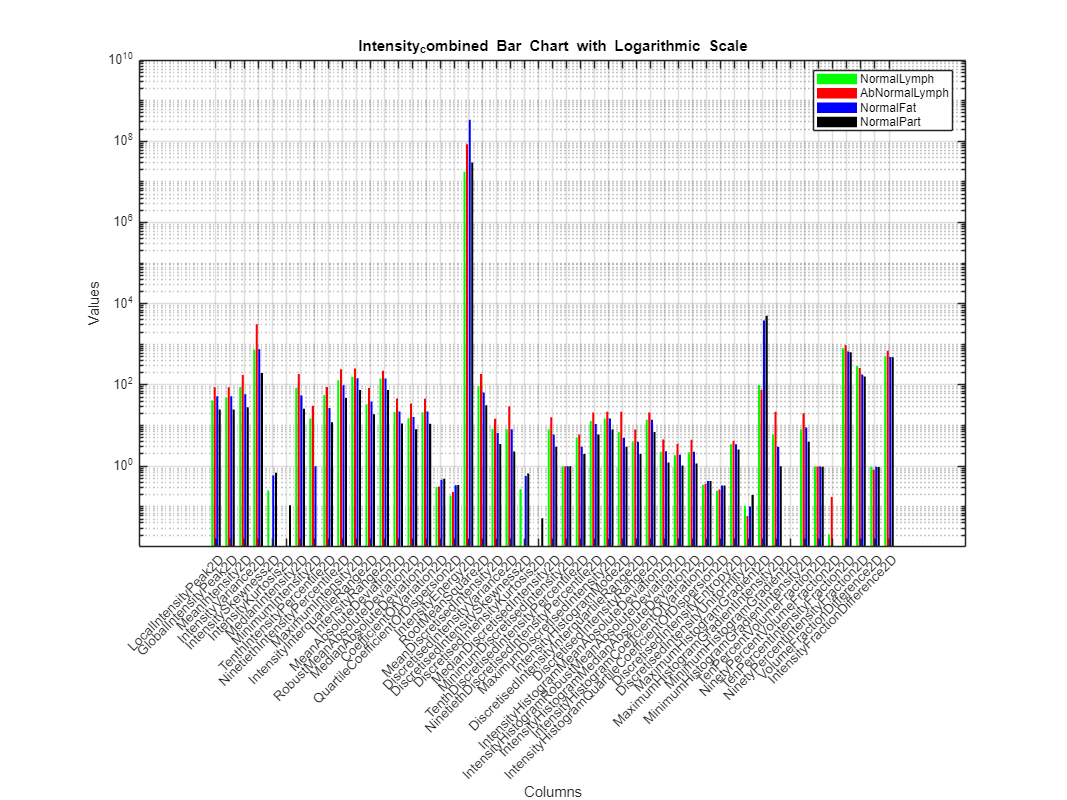

yLimits = ylim; % Get current y-axis limits

xlim([xLimits(1) - xPadding, xLimits(2) + xPadding]); % Extend x-axis
ylim([yLimits(1) - yPadding, yLimits(2) + yPadding]); % Extend y-axis
% Get the screen size
% To resize the figure window, you can set the 'Position' property
set(gcf, 'Position', [1, 1, 4800, 3600]); % Example: [left, bottom, width, height]

% find maximum variance for Intensity


% Calculate variance for each column in the table
columnVariances = var(table2array(Intensity_combined)); % Convert table to matrix and calculate variance

% Sort the variances in descending order and get the indices of the top 10
[~, sortedIndices] = sort(columnVariances, 'descend');

numTopColumns = 10; % Number of top columns you want to select
top10Indices = sortedIndices(1:numTopColumns);

% Extract the top 10 columns from the table
top10Columns = Intensity_combined(:, top10Indices);

% Display results
disp('Names of the top 10 columns with maximum variance:');

Names of the top 10 columns with maximum variance:


disp(Intensity_combined.Properties.VariableNames(top10Indices));

    {'IntensityEnergy2D'}    {'MaximumHistogramGradient2D'}    {'IntensityVariance2D'}    {'MinimumHistogramGradient2D'}    {'TenPercentIntensityFraction2D'}    {'IntensityFractionDifference2D'}    {'NinetiethIntensityPercentile2D'}    {'MaximumIntensity2D'}    {'MedianIntensity2D'}    {'RootMeanSquare2D'}



disp('Top 10 columns data:');

Top 10 columns data:


disp(top10Columns);

                     IntensityEnergy2D    MaximumHistogramGradient2D    IntensityVariance2D    MinimumHistogramGradient2D    TenPercentIntensityFraction2D    IntensityFractionDifference2D    NinetiethIntensityPercentile2D    MaximumIntensity2D    MedianIntensity2D    RootMeanSquare2D
                     _________________    __________________________    ___________________    __________________________    _____________________________    _____________________________    ______________________________    __________________    _________________    ________________

    NormalLymph         1.7657e+07                   99.5               

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%plot descending order texture feature

% Number of rows and columns in the table
[numRows, numCols] = size(top10Columns);

% Define colors for the bars
colors = [0, 1, 0; 1, 0, 0; 0, 0, 1; 0, 0, 0]; % Green, Red, Blue, Black
colorNames = {'Green', 'Red', 'Blue', 'Black'};

figure;

% Create a bar chart with groups of bars for each column
hBar = bar(table2array(top10Columns)', 'grouped'); 

% Set colors for each group of bars
for i = 1:numRows
    hBar(i).FaceColor = colors(i, :);
end

        % Set the y-axis to logarithmic scale
        set(gca, 'YScale', 'log');

% Add labels and title
xlabel('Columns');
ylabel('Values');
title('Top 10 descending variance Bar Chart  for  Intensity feature  Log');

% Set x-axis labels to column names
xticks(1:numCols);
xticklabels(top10Columns.Properties.VariableNames);

% Create custom legend with color names
Intensity_combined.Properties.RowNames = {'NormalLymph', 'AbNormalLymph', 'NormalFat', 'NormalPart'};

legendEntries = cell(numRows, 1); % Initialize cell array for legend entries
for i = 1:numRows
    legendEntries{i} = sprintf('%s',Intensity_combined.Properties.RowNames{i});
end
legend(hBar, legendEntries, 'Location', 'best');

% Display grid
grid on;
% Adjust axis limits with padding
xPadding = .5; 
yPadding = .5; 

% Extend x-axis and y-axis limits
xLimits = xlim; 

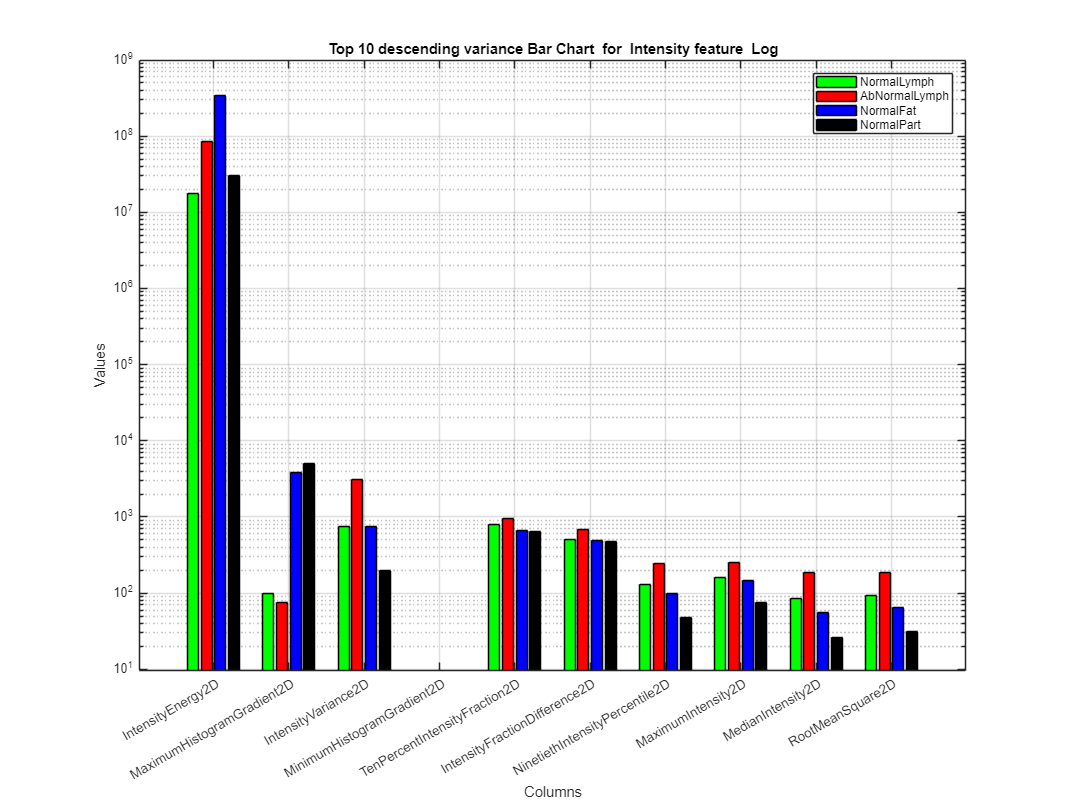

yLimits = ylim; 

xlim([xLimits(1) - xPadding, xLimits(2) + xPadding]); 
ylim([yLimits(1) - yPadding, yLimits(2) + yPadding]); 

set(gcf, 'Position', [1, 1, 4800, 3600]); %  [left, bottom, width, height]